# Here I'll attemt to replicate some of the figures in the Watson 14 paper

clear all; clc; close all;
%load data
dataLoad_all;

## plot Curcio Cone Densities in deg (figure 1)

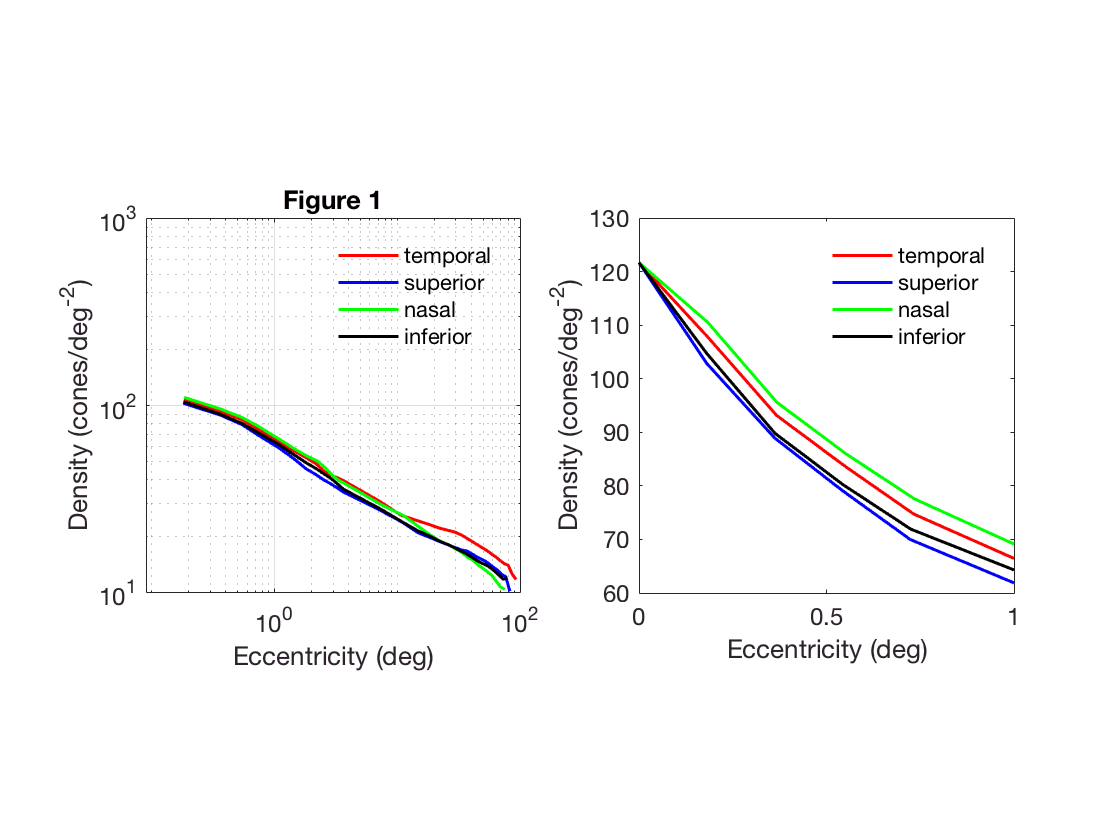

figure;
subplot(1,2,1);loglog(xt_deg_c,yt_deg_c,'r',xs_deg_c,ys_deg_c,'b',xn_deg_c,yn_deg_c,...
'g',xi_deg_c,yi_deg_c,'k','linewidth',1.5);
xlim([0.09 100]); xlabel('Eccentricity (deg)'); ylabel('Density (cones/deg^-^2)');
legend('temporal','superior','nasal','inferior'); legend('boxoff');axis square
title('Figure 1'); grid on;
%plot only first degree
subplot(1,2,2);plot(xt_deg_c(1:6),yt_deg_c(1:6),'r',xs_deg_c(1:6),ys_deg_c(1:6)...
,'b',xn_deg_c(1:6),yn_deg_c(1:6),'g',xi_deg_c(1:6),yi_deg_c(1:6),'k','linewidth',1.5);
xlim([0 1]); xlabel('Eccentricity (deg)'); ylabel('Density (cones/deg^-^2)');
legend('temporal','superior','nasal','inferior'); legend('boxoff');axis square

## Plot Curcio Retinal Ganglion Cell Densities (figure 2)

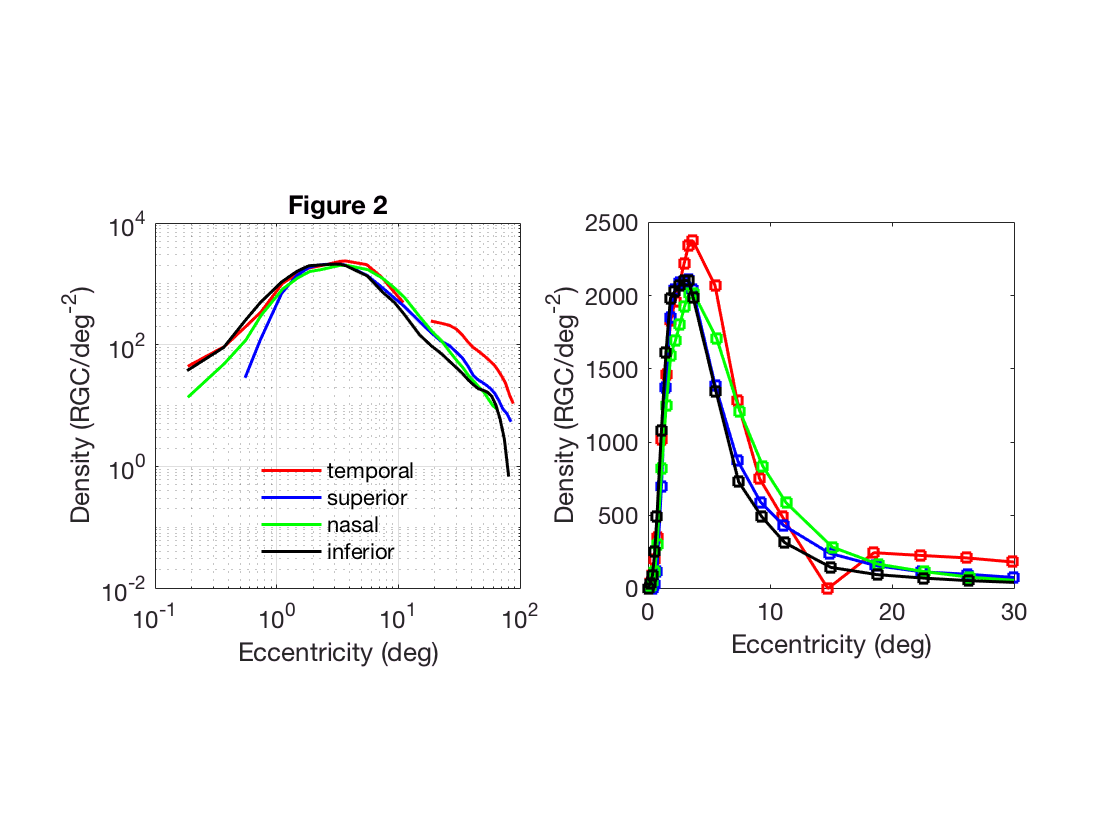

figure;
subplot(1,2,1);loglog(xt_deg_rgcd,yt_deg_rgcd,'r',xs_deg_rgcd,ys_deg_rgcd,'b',xn_deg_rgcd,yn_deg_rgcd,...
'g',xi_deg_rgcd,yi_deg_rgcd,'k','linewidth',1.5);
xlim([0.1 100]); xlabel('Eccentricity (deg)'); ylabel('Density (RGC/deg^-^2)');
legend('temporal','superior','nasal','inferior'); legend('boxoff');
legend('location','south');axis square;title('Figure 2'); grid on;
%plot only first twenty degree
subplot(1,2,2);plot(xt_deg_rgcd(1:30),yt_deg_rgcd(1:30),'-sr',xs_deg_rgcd(1:30),ys_deg_rgcd(1:30),...
'-sb',xn_deg_rgcd(1:30),yn_deg_rgcd(1:30),'-sg',xi_deg_rgcd(1:30),yi_deg_rgcd(1:30),'-sk','linewidth',1.5);
xlim([0 30]); xlabel('Eccentricity (deg)'); ylabel('Density (RGC/deg^-^2)'); axis square; hold on

## plot Total RGC count (figure 3)

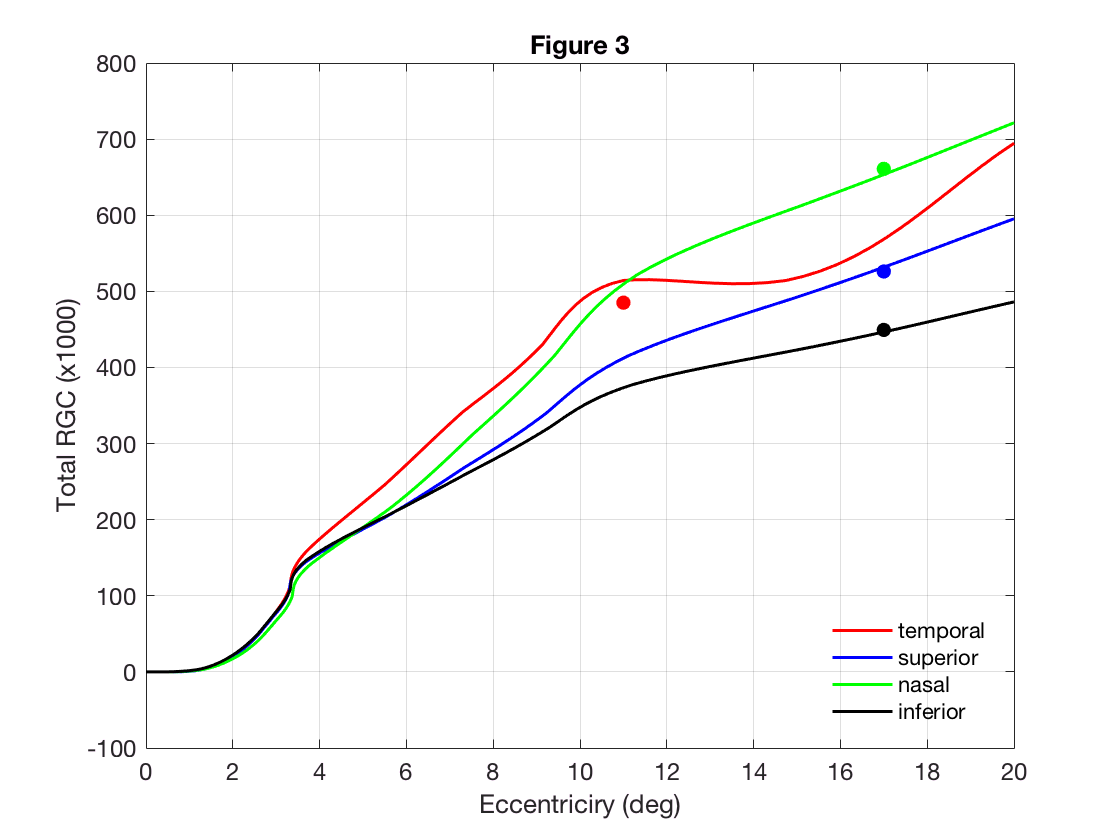

rgc_count;
%interpolate x-axis for diff x-vals
for xx = 1:length(eccIdx)
    xdata = eval(x_nameIdx{xx});
    xinterp = xdata(1:eccIdx(xx));
    x_vals(:,xx) = interp(xinterp,10);
    clear xinterp
end
%plot all interpolated data
figure;
plot(x_vals(:,3),locInt(:,3),'r',x_vals(:,4),locInt(:,4),'b',x_vals(:,2),locInt(:,2),...
'g',x_vals(:,1),locInt(:,1),'k','linewidth',1.5); grid on;
legend('temporal','superior','nasal','inferior'); legend('boxoff'); legend('location','southeast')
xlim([0 20]); ylabel('Total RGC (x1000)'); xlabel('Eccentriciry (deg)'); hold on;
title('Figure 3')
%plot displacement zone
%data points taken from table in paper
%not sure why the lines arent an exact match - specially for the temporal retina
h1 = plot(11,485.1,'.r','markersize',20); h2 = plot(17,660.9,'.g','markersize',20); 
h3 = plot(17,526.1,'.b','markersize',20); h4 = plot(17,449.3,'.k','markersize',20);

%remove legend markers for displacement zone
set(get(get(h1,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
set(get(get(h2,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
set(get(get(h3,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
set(get(get(h4,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
% Not sure why the displacement zone doesn't match for temporal retina
% I followed the math in the paper...

## fit area outside displacement zone (figure 4)

titleNames = {'temporal','Superior','Nasal','Inferior'}; 
x_nameIdx = {'xt_deg_rgcd','xs_deg_rgcd','xn_deg_rgcd','xi_deg_rgcd'}; 
y_nameIdx = {'yt_deg_rgcd','ys_deg_rgcd','yn_deg_rgcd','yi_deg_rgcd'}; 
opt = optimoptions('fmincon','Algorithm','interior-point','MaxIter',10000);
% initial values for optmization
% taken from paper (table 1) ... fmincon was not arriving at best vals on
% its own. Thought Id help it out...turns out it doesnt really...somethings
% weird when I fit all the eccentricities. 
% x0_init = [0.9851,1.058,22.14;...
%            0.9935,1.035,16.35;...
%            0.9729,1.084,7.633;...
%            0.9960,0.9932,12.13];
for ii = 1:length(x_nameIdx)
    if ii ==1 
        dispZoneIdx =12; %17
    else
        dispZoneIdx =19; %19
    end
    y = eval(y_nameIdx{ii}); y = y(dispZoneIdx:end)'; 
    ecc = eval(x_nameIdx{ii}); ecc = ecc(dispZoneIdx:end)';
    %free paramaters
    %1-first term weight
    %2-ecc at which density is reduced by factor of four
    %3-scale factor of exponential
    %bounds where chosen to be in proximity to actual values used in the paper (table 1)
	ub = [1, 2, 25];  %upper bound
	lb = [-1, 1, 7];  %lower bound
    %ub = x0_init(ii,:); lb = x0_init(ii,:);
    %x0 = x0_init(ii,:); %starting values - chosen as best fits from paper (table 1)
    x0 = [0.97,1.035,15];
    f = @(x)fit_displacementZone(x,y,ecc);
    [x,fval,exitflag,output,grad,hessian] = fmincon(f,x0,[],[],[],[],lb,ub,[],opt);
    %center,gain,sigma,p,base
    [~,temp] = fit_displacementZone(x,y,ecc);
    %store vars 
    fittedVals{ii} = temp;
    ogecc{ii} = ecc;
    ogy{ii}=y;
    params(:,ii) = x;
    clear temp ecc y 
    %interpolate to match xvals
    %interpFit{ii} = interp(temp,3);
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>




Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>




Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>




Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>



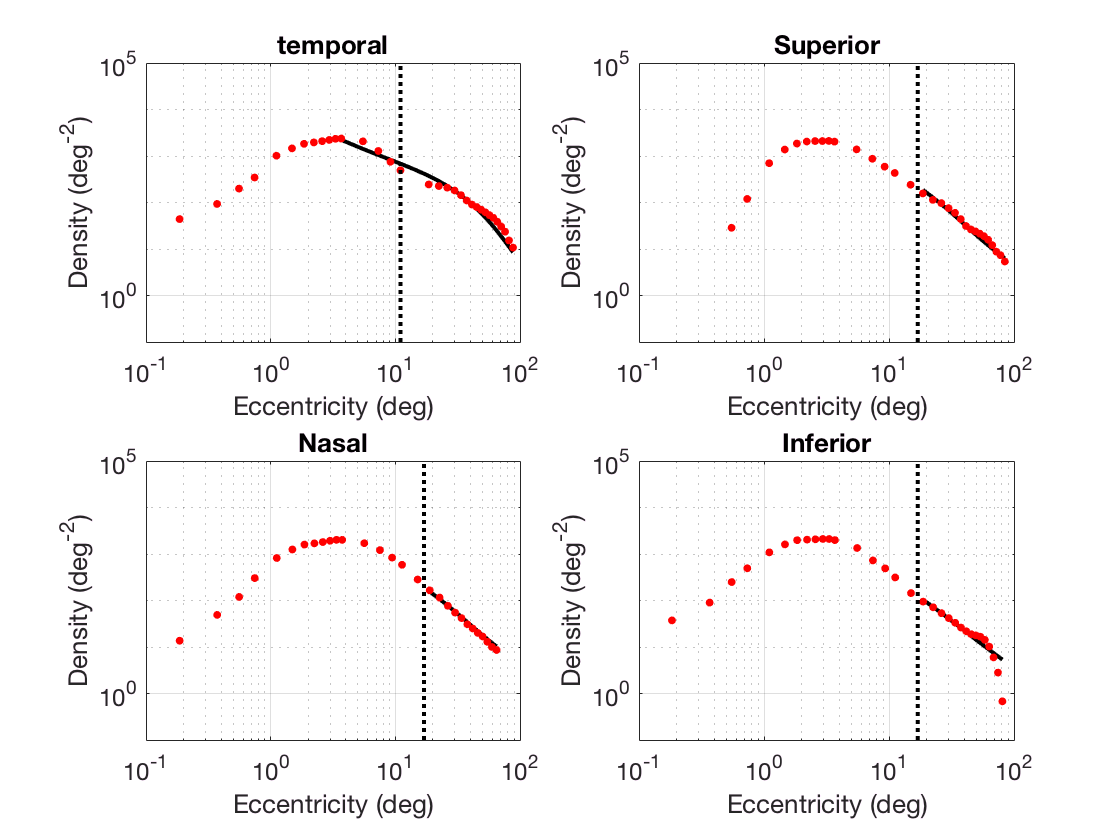


% plot data points (figure 4)
figure;
for ii = 1:length(x_nameIdx)
    subplot(2,2,ii);loglog(ogecc{ii},fittedVals{ii},'-k','linewidth',2); hold on; grid on
    subplot(2,2,ii);loglog(eval(x_nameIdx{ii}),eval(y_nameIdx{ii}),'.r','markersize',10); 
    xlim([0.1 100]); ylim([0.1 10^5])
    if ii == 1
        line([11, 11],ylim,'linestyle',':','color','k','linewidth',2);
    else
        line([17, 17],ylim,'linestyle',':','color','k','linewidth',2);
    end
    xlabel('Eccentricity (deg)'); ylabel('Density (deg^-^2)');
    title(titleNames{ii}); 
end

## Use fitted params to plot entire curve

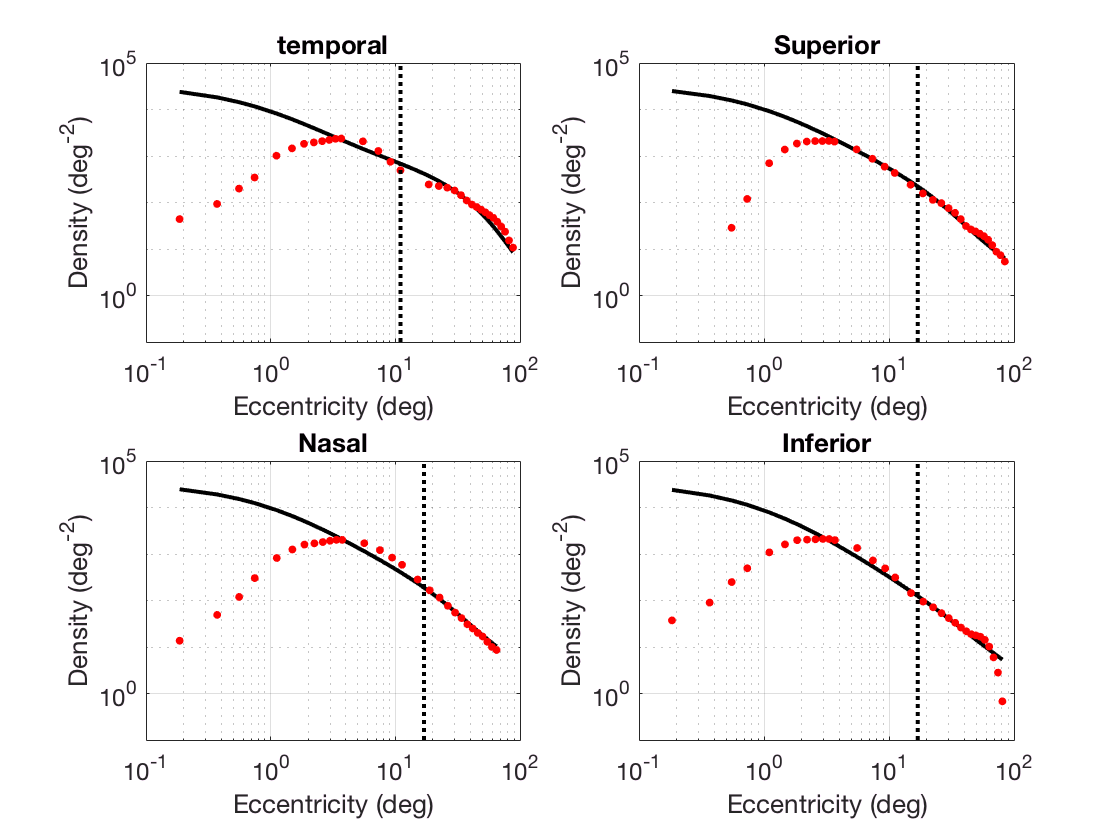

for ii = 1:length(x_nameIdx)
    y = eval(y_nameIdx{ii}); y = y(1:end)'; 
    ecc = eval(x_nameIdx{ii}); ecc = ecc(1:end)';
    [~,fit{ii}] = fit_displacementZone(params(:,ii),y,ecc);
    ogecc{ii} = ecc;
end
%plot
figure;
for ii = 1:length(x_nameIdx)
    subplot(2,2,ii);loglog(ogecc{ii},fit{ii},'-k','linewidth',2); hold on; grid on
    subplot(2,2,ii);loglog(eval(x_nameIdx{ii}),eval(y_nameIdx{ii}),'.r','markersize',10); 
    xlim([0.1 100]); ylim([0.1 10^5])
    if ii == 1
        line([11, 11],ylim,'linestyle',':','color','k','linewidth',2);
    else
        line([17, 17],ylim,'linestyle',':','color','k','linewidth',2);
    end
    xlabel('Eccentricity (deg)'); ylabel('Density (deg^-^2)');
    title(titleNames{ii}); 
end

paper_p = [0.9851,1.058,22.14;...
           0.9935,1.035,16.35;...
           0.9729,1.084,7.633;...
           0.9960,0.9932,12.13];
%seems like fmincon does a better job of fitting the points ... there are
%some big differences in the last parameter
disp('Here are the fmincon params:'); 

Here are the fmincon params:


disp('Each column is a retinal location (from left: temporal/superior/nasal/inferior)');

Each column is a retinal location (from left: temporal/superior/nasal/inferior)


disp(num2str(params)); 

0.973617     0.984413     0.988507     0.997436
 1.02248      1.18199      1.15004      1.03713
 16.5155      9.32497      8.98717      9.74558


disp('Here are the paper params:');

Here are the paper params:


disp(num2str(paper_p')); 

0.9851       0.9935       0.9729        0.996
 1.058        1.035        1.084       0.9932
 22.14        16.35        7.633        12.13
 


## replot the fits in their own plot (figure 5)

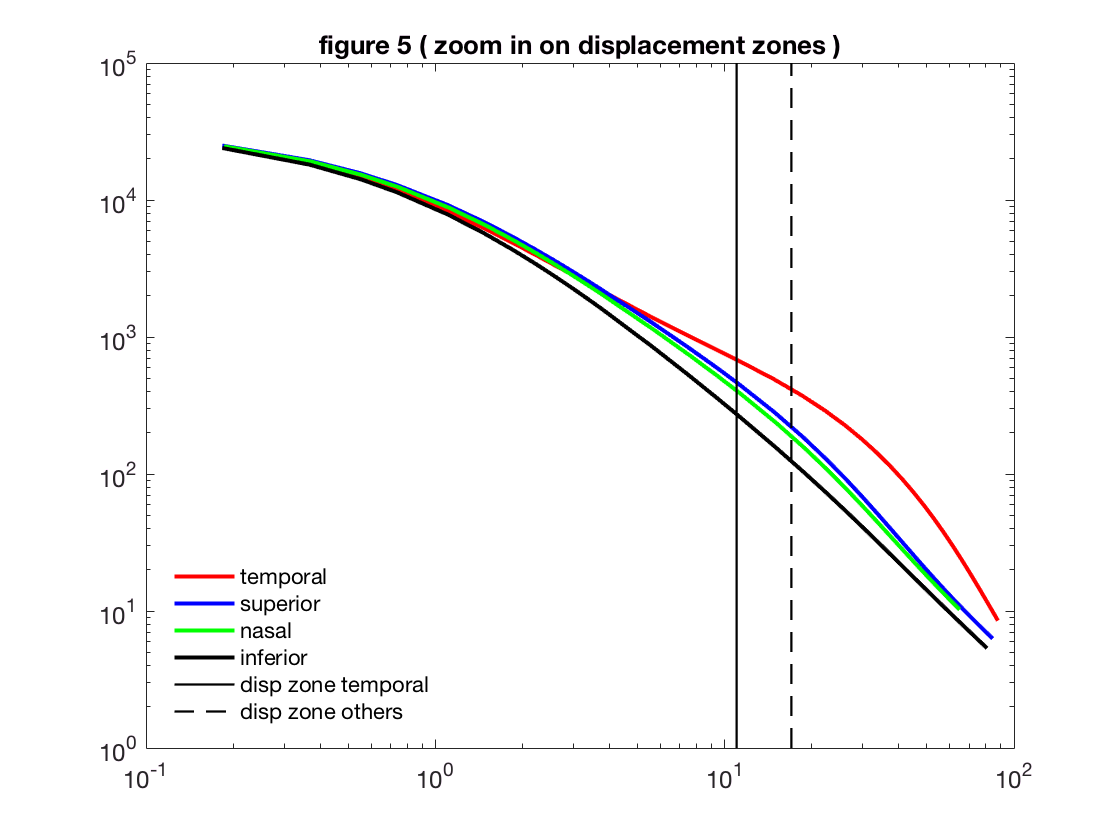

figure;
loglog(ogecc{1},fit{1},'r',ogecc{2},fit{2},'b',...
    ogecc{3},fit{3},'g',ogecc{4},fit{4},'k','linewidth',2);
%xlim([8 100]);
line([11 11],ylim,'color','k','linestyle','-');
line([17 17],ylim,'color','k','linestyle','--');
legend('temporal','superior','nasal','inferior',...
    'disp zone temporal','disp zone others'); 
legend('boxoff'); legend('location','southwest');
title('figure 5 ( zoom in on displacement zones )');